# Modeling migration by a daily amplitude and a residus

This current script present a model which decomposes the log-transform of the row signal of migration, *Z,  *into two signals: a daily amplitude *A* and a residus *R*. The amplitude is average bird density during a night at each location, such that it becomes a daily spatio-temporal  signal. A polynomial curve c is fit together with the amplitude to take into acount the variation during a night. The time is normalized according to sunset (-1) and sunrise (1). The residus is the unexplained signal of this daily amplitude. It also shows a spatio-temporal correlation.


$$\log \left(Z\left(t,s\right)\right)=A\left(t_{\textrm{day}} ,s\right)\cdot c\left(t_{\textrm{hr}} ,p\right)+R\left(t,s\right)$$


The fitted curve c is simply fitted together with the amplitude at all the radar and all night. The ammplitude and residus are close to normal distributed so that a normla score is acceptable. The covariance parameter of both variable are fitted on the data with a Gneiting model. Then, using kriging, we can simulate the spatial temporal model. Validation is performed by removing a radar, and simulating it based on the others one. 

## 1. Import and create data

clear all; load('./data/dc_corr.mat'); addpath('functions/')


Convert the volumetric densit to a surface densisty (`denss`)

for i_d=1:numel(dc)
    weight=diff(double([0 max(0, (1:dc(i_d).levels).*dc(i_d).interval - dc(i_d).height )]))/1000;
    dc(i_d).denss = dc(i_d).dens*weight';
    dc(i_d).scoret = datenum(dc(i_d).time'-mean([dc(i_d).sunrise;dc(i_d).sunset])) ./ datenum(dc(i_d).sunrise-dc(i_d).sunset)*2;
end

Create the data structure `data`

dens_lim = 0;
data=[];
uniqueDate = round(datenum(datetime(start_date-1:end_date-1)));
for i_d=1:numel(dc)
    id = dc(i_d).scoret(:)>=-1 & dc(i_d).scoret(:)<=1 & dc(i_d).denss>dens_lim;
    d=table();
    d.dens=dc(i_d).denss(id);
    d.scoret = dc(i_d).scoret(id)';
    d.i_d=i_d*ones(sum(id),1);
    d.lat=dc(i_d).lat*ones(sum(id),1);
    d.lon=dc(i_d).lon*ones(sum(id),1);
    d.time = datenum(dc(i_d).time(id));
    radardate = round(datenum(dc(i_d).sunrise(id)))';
    [~,i_t]=ismember(radardate,uniqueDate);
    d.dateradar = sub2ind([numel(dc) numel(uniqueDate)],repmat(i_d,numel(radardate),1),i_t);
    d.wind = [dc(i_d).u(id,:) dc(i_d).u10(id) dc(i_d).u100(id) dc(i_d).v(id,:)  dc(i_d).v10(id) dc(i_d).v100(id)];
    d.temperature = dc(i_d).t(id,:);
    data = [data ; d ];
end
data.logdens=(data.dens).^(1/5);


## 2. Amplitude and cuve parameters

This section's purpuse is to find the value of *A* and paramaters of the polynomial *p* which fit best the data. We first find them seperatively and then perform a min-search of the equation combined.


$$\log \left(Z\left(t,s\right)\right)=S\left(s\right)+A\left(t_{\textrm{day}} ,s\right)+c\left(t_{\textrm{hr}} ,p\right)$$


Initialize S by simply finding the average of  each radar

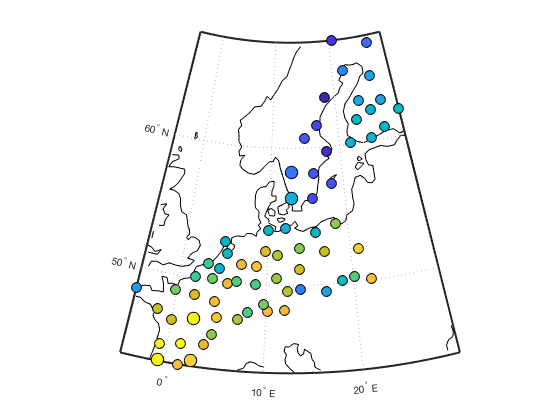

S0=zeros(numel(dc), 1);
for i_d=1:numel(dc)
    S0(i_d)=mean(data.logdens(data.i_d==i_d));
end

figure; load coastlines; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,S0,'filled','MarkerEdgeColor','k');

Initialize A by simply finding the average of the night for each radar

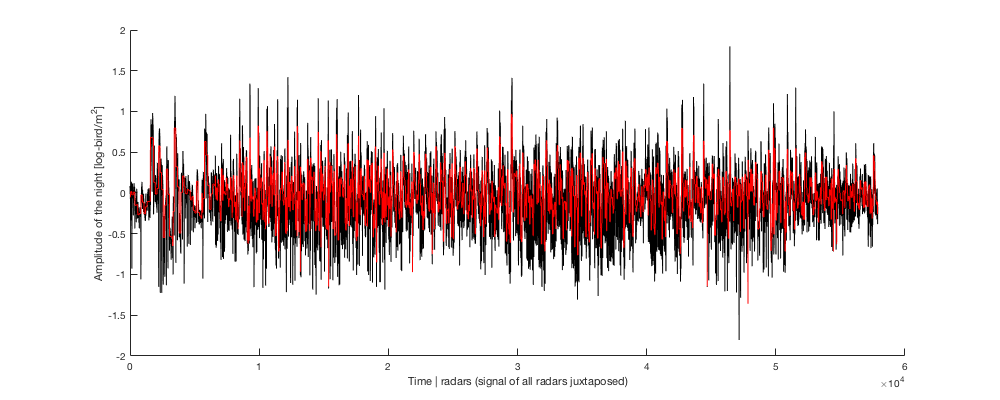

A0=zeros(numel(dc), numel(uniqueDate));
for i=1:numel(A0)
    A0(i)=mean(data.logdens(data.dateradar==i));
end
A0=A0-repmat(S0,1,numel(uniqueDate));

figure('position',[0 0 1000 400]); hold on; plot(data.logdens-S0(data.i_d),'k'); plot(A0(data.dateradar),'r');
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]')

Intialize the polyfit parameter by the residual of A for all radars. 

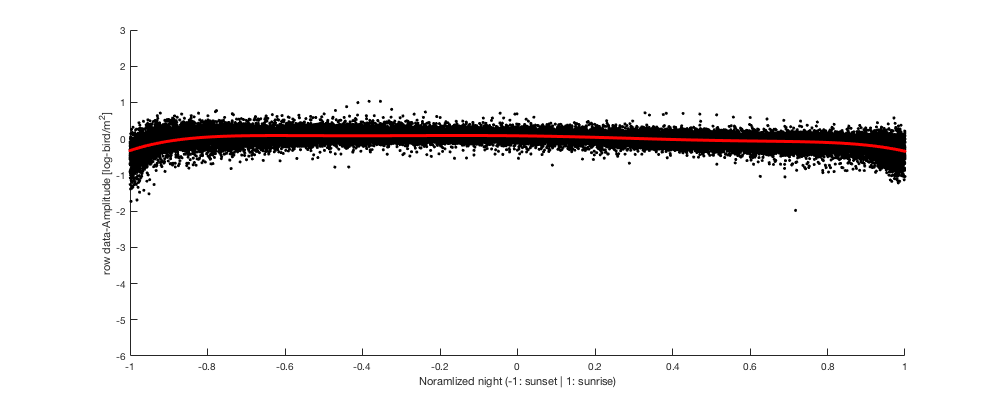

nb_poly=6;
p0 = polyfit(data.scoret,data.logdens-S0(data.i_d)-A0(data.dateradar),nb_poly);
figure('position',[0 0 1000 400]); hold on; plot(data.scoret,data.logdens-S0(data.i_d)-A0(data.dateradar),'.k'); plot(data.scoret, polyval( p0, data.scoret ),'.r'); ylim([-6 3])
xlabel('Noramlized night (-1: sunset | 1: sunrise)'); ylabel('row data-Amplitude [log-bird/m^2]')

Performing an optimazation of the amplitude and polyfit parameter combined. 

rmse = @(x) nansum( ( pred2(x,numel(dc),numel(uniqueDate),nb_poly,data)  - data.logdens ).^2 );
% options = optimset('PlotFcns',@optimplotfval,'MaxFunEvals',10000);
options = optimset('MaxFunEvals',1000);
x = fminsearch(rmse,[S0(:);A0(:);p0(:)],options);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 1254.307602 



Sf = reshape(x(1:numel(dc)),numel(dc),1);
Af = reshape(x(numel(dc)+(1:numel(dc)*numel(uniqueDate))),numel(dc),numel(uniqueDate));
pf = x(end-nb_poly:end);

Figure

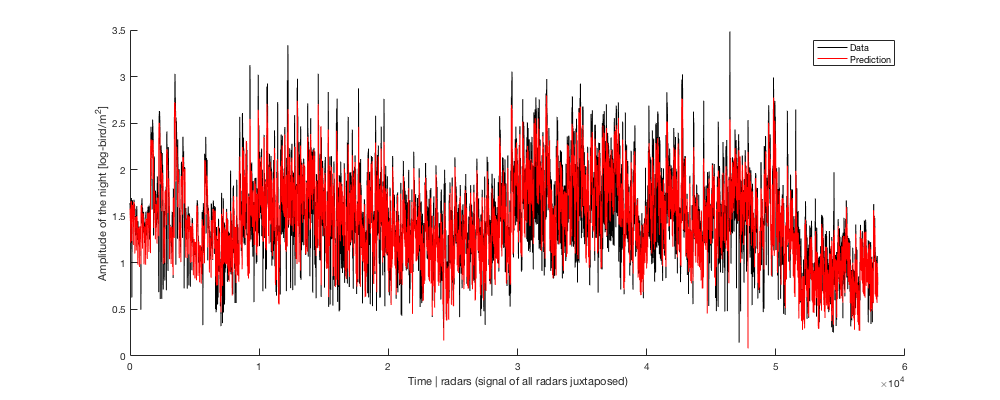

figure('position',[0 0 1000 400]); hold on; plot(data.logdens,'k'); plot(pred2([Sf(:);Af(:);pf(:)],numel(dc),numel(uniqueDate),nb_poly,data),'r'); 
xlabel('Time | radars (signal of all radars juxtaposed)'); ylabel('Amplitude of the night [log-bird/m^2]'); legend('Data','Prediction')

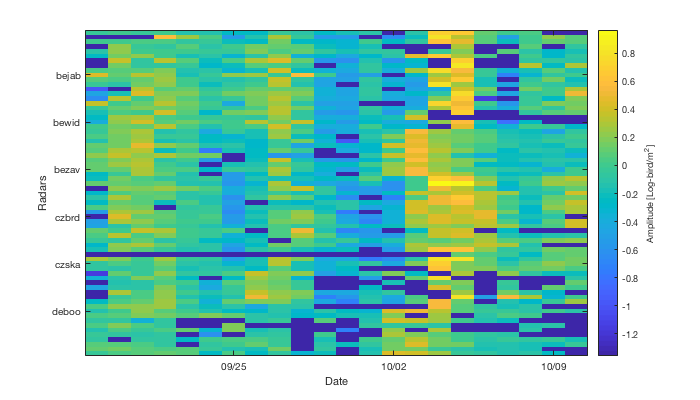

figure('position',[0 0 700 400]); imagesc(uniqueDate,1:numel(dc), Af); datetick('x'); axis tight; c = colorbar; yticklabels({dc.name});
xlabel('Date'); ylabel('Radars');c.Label.String = 'Amplitude [Log-bird/m^2]';

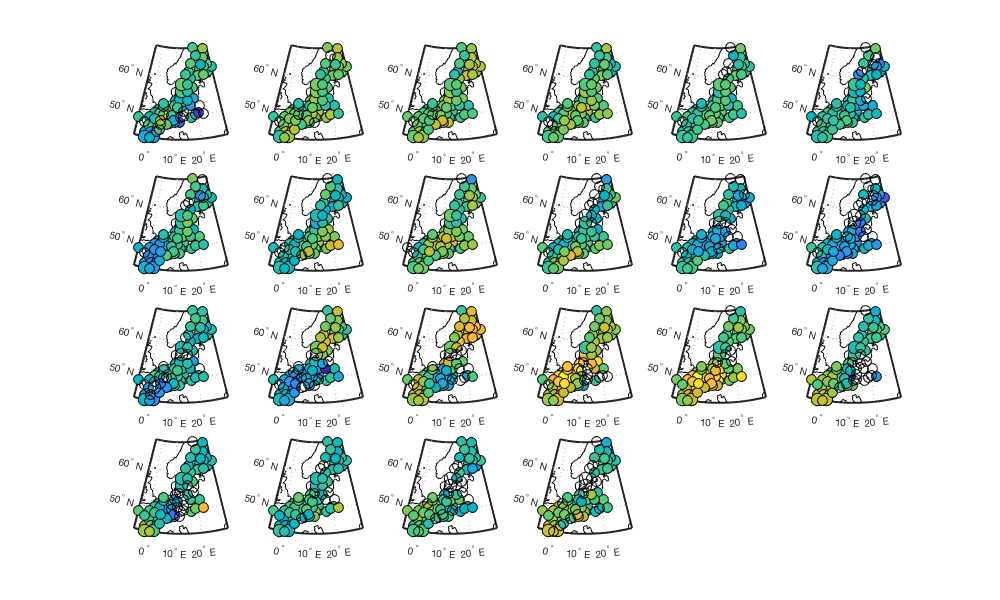

figure('position',[0 0 1000 600]); load coastlines; c_caxis=[min(Af(:)) max(Af(:))];
for i_date = 1:numel(uniqueDate)
    subplot(4,6,i_date); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,Af(:,i_date),'filled','MarkerEdgeColor','k');
    caxis(c_caxis);
end

## Covariable S

missing pressure...

CovariableS=zeros(numel(dc), 4);

for i_d=1:numel(dc)
    CovariableS(i_d,1)=mean(data.temperature(data.i_d==i_d,1));
    CovariableS(i_d,2)=mean(data.wind(data.i_d==i_d,1));
    CovariableS(i_d,3)=mean(data.wind(data.i_d==i_d,9));
    CovariableS(i_d,4)=dc(i_d).height;
end

Same for the 6 elevations. 


figure('position',[0 0 1000 600]); load coastlines;
subplot(2,4,[1 2 5 6]); hold on; worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]);  plotm(coastlat, coastlon,'k')
scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,Sf,'filled','MarkerEdgeColor','k'); title('Sf');
ii=[3 4 7 8]; tt={'temperature','wind WE','wind NS','elevation'};

tt = 1×4 cell array
    {'temperature'}    {'wind WE'}    {'wind NS'}    {'elevation'}


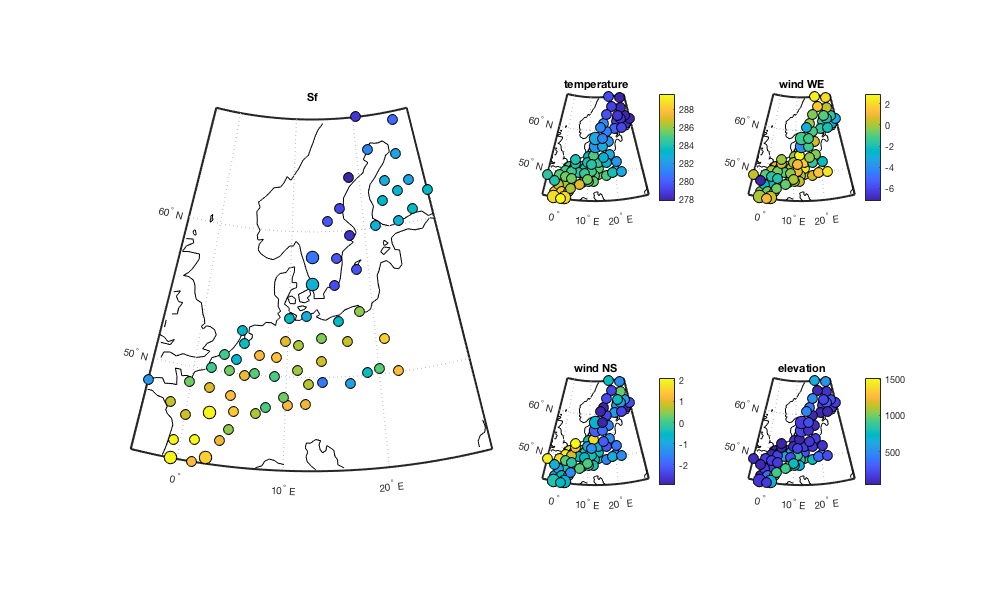

for i=1:size(CovariableS,2)
    subplot(2,4,ii(i)); hold on; title(tt{i});
    worldmap([min([dc.lat]) max([dc.lat])], [min([dc.lon]) max([dc.lon])]); plotm(coastlat, coastlon,'k')
    scatterm([dc.lat],[dc.lon],[dc.maxrange]*4,CovariableS(:,i),'filled','MarkerEdgeColor','k'); colorbar;
end

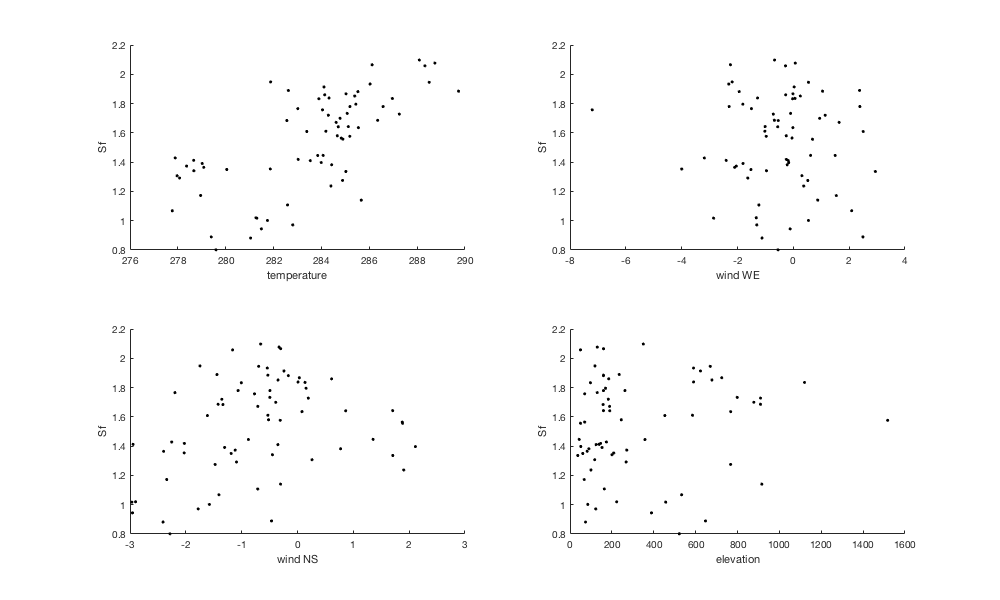


figure('position',[0 0 1000 600]); 
for i=1:size(CovariableS,2)
    subplot(2,2,i); hold on; 
    scatter(CovariableS(:,i),Sf,'.k')
    ylabel('Sf'); xlabel(tt{i})
end

## Covariable A

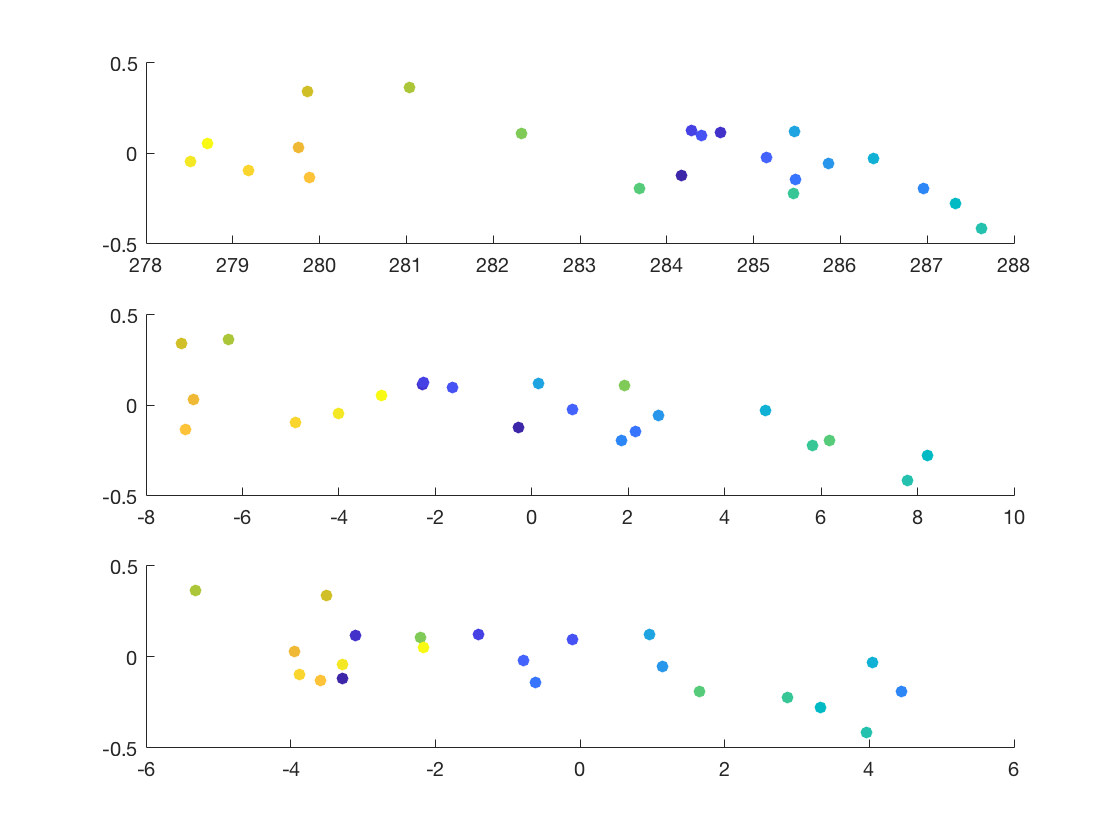



CovariableA=zeros(numel(dc), numel(uniqueDate),3);
for i=1:size(CovariableA,1)
    for j=1:size(CovariableA,2)
        ij = sub2ind(size(CovariableA),i,j);
        CovariableA(i,j,1)=nanmean(data.temperature(data.dateradar==ij,1));% - mean(data.temperature(data.i_d==i,1));
        CovariableA(i,j,2)=nanmean(data.wind(data.dateradar==ij,1));%-mean(data.wind(data.i_d==i,1));
        CovariableA(i,j,3)=nanmean(data.wind(data.dateradar==ij,9));%-mean(data.wind(data.i_d==i,9));
    end
end

figure; 
for i=1:size(CovariableA,3)
    subplot(3,1,i);scatter(nanmean(CovariableA(:,:,i),1),nanmean(Af,1),[],uniqueDate,'filled')
end

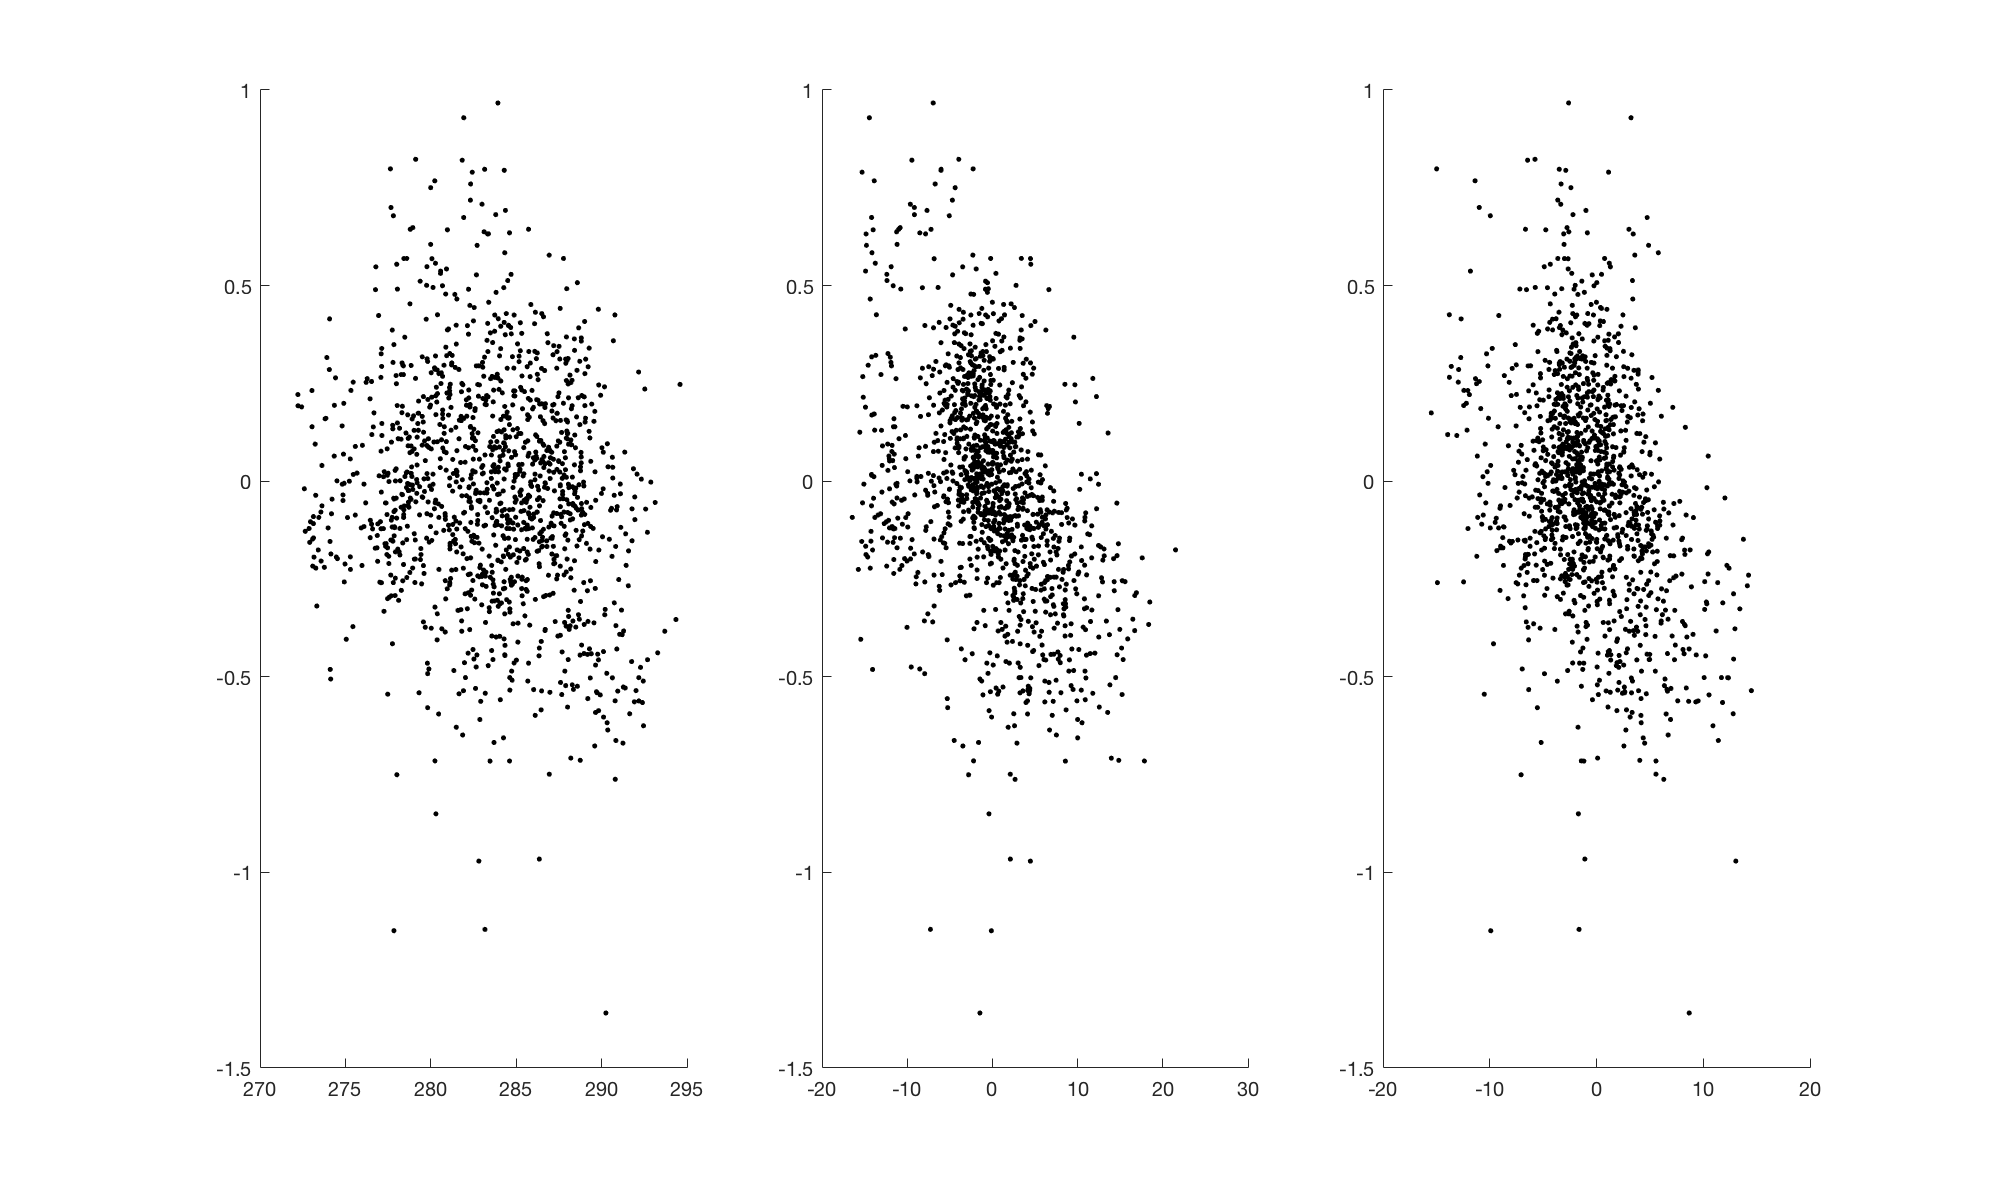


figure('position',[0 0 1000 600]); 
for i=1:size(CovariableA,3)
    subplot(1,3,i); hold on; 
    a=CovariableA(:,:,i);
    scatter(a(:),Af(:),'.k')
end